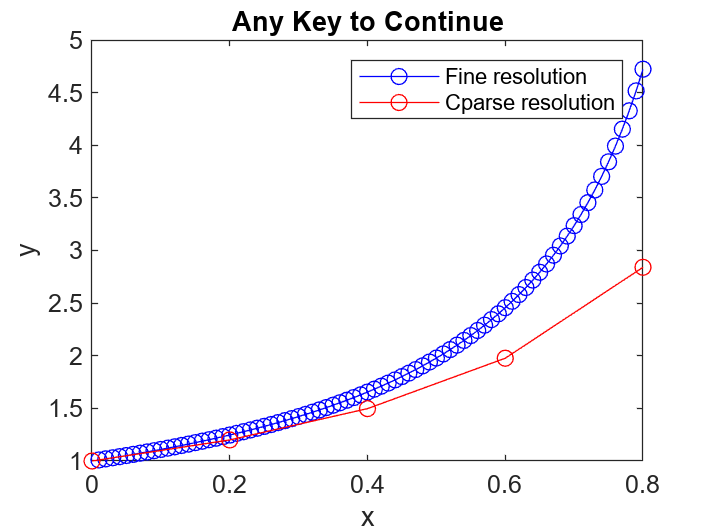

% solving differential equations...
% hill 
% oct 2013

clear all
close all
clc

%let us first consider ordinary differential equations. These come as
%'initial value' or 'boundary value' problems. In addition, they can be
%first, second, etc. 'order' depending upon the highest derivative.

%% Block 1
%first order initial value problem.

% dy / dx - xy^2 - y = 0;   y(0) = 1;

%rephrase as dy / dx = f(x,y); f = xy^2+y

%Simple Euler method:
% dy / dx ~ [y_(n+1) - y_(n)] dx
% thus, y_(n+1) = f(x,y) * dx + y_(n)
% So, you can compute y at 'next' grid point based upon values at present
% grid point. This is very simple to do in a for loop structure. One
% potential problem has to do with stability. Another has to do with poor
% accuracy.

%TEST
clear all
close all
clc

xmin=0;
xmax=.8;
dx=.01;
x=[xmin:dx:xmax];
y(1)=1;
for j=1:length(x)-1
    f=x(j)*y(j)^2+y(j);
    y(j+1)=f*dx+y(j);
end
figure(1)
plot(x,y,'b-o');xlabel('x');ylabel('y');
hold on

%redo with poor resolution
dx=.2;
clear x y
x=[xmin:dx:xmax];
y(1)=1;
for j=1:length(x)-1
    f=x(j)*y(j)^2+y(j);
    y(j+1)=f*dx+y(j);
end

plot(x,y,'r-o');xlabel('x');ylabel('y');
legend('Fine resolution','Cparse resolution')
title('Any Key to Continue')

pause

%look at another example, to show instability issue...
% dy / dx + y = 0; y(0) = 1 --> easy analytic solution (y=exp(-x))

clear all
xmin=0;
xmax=10;
dx=0.5;
x=[xmin:dx:xmax];
y(1)=1;
for j=1:length(x)-1
    f=-y(j);
    y(j+1)=f*dx+y(j);
end
figure(2)
plot(x,y);xlabel('x');ylabel('y');

%redo with poor resolution
dx=3;
clear x y
x=[xmin:dx:xmax];
y(1)=1;
for j=1:length(x)-1
    f=-y(j);
    y(j+1)=f*dx+y(j);
end
figure(2); hold on
plot(x,y,'r');xlabel('x');ylabel('y');

% add exact solution
x=linspace(0,10,1000);
plot(x,exp(-x),'c')
axis([0 10 -3 4]) 

legend('fine','coarse','exact')

%% Block 2
% first order ODE, solution with matlab functions (ODE45). The above is a
% very low order solution method, with large potential errors. Higher order
% solutions (Runge-Kutta) above. They are better since the truncation error
% is less.

clear all
close all
xmin=0;
xmax=.9;
y0=1;
f=@(x,y) x*y^2+y;
[x,y]=ode45(f,[xmin xmax],y0);
figure(3); hold off
plot(x,y,'b.')
xlabel('x');ylabel('y');
hold on
% note that, in this case, Matlab figures out the discretization needed in
% the x. Let us go back and add our simple Euler solution

clear all
xmin=0;
xmax=.9;
dx=.1;
x=[xmin:dx:xmax];
y(1)=1;
for j=1:length(x)-1
    f=x(j)*y(j)^2+y(j);
    y(j+1)=f*dx+y(j);
end
plot(x,y,'r-o');legend('ODE45','Simple Euler')

% note: rather than using anonymous / inline functions, you can have an
% external function written into another mfile.

% --> Inclass example. Have students solve dy / dx = -sin(x); y(0) = 1 over
% the domain 0 < x < 2 * pi. Can use either simple Euler or ODE45.


%% Block 2.1
% 'stiff' ODEs. No precise definition; a stiff ODE is one where a certain
% term can lead to very rapid variation in the numerical solution.

% Consider first
% y' = y - t^2;   y(0) = 2
% solve over 0 < t < 10

% Use basic euler

clear all
close all
clc

tmin=0; tmax=10; dt=0.25;
t=tmin:dt:tmax;
y(1)=2;
y0=y(1);
for j=1:length(t)-1
    f=y(j)-t(j)^2;
    y(j+1)=y(j)+dt*f;
end
figure(1)
plot(t,y,'b-o')

% try ode45
f=@(t,y) y-t^2
[t,y]=ode45(f,[tmin tmax],y0);
hold on
plot(t,y,'r.')
legend('simple euler','ode45','location','southwest')

%% Block 3
% What if we have a coupled system of first order ODEs? We can't write that
% into an anonymous function, so we tackle with a separate file.

% dx / dt = -sigma * x + sigma * y
% dy / dt = rho * x - y - x * z
% dz / dt = -beta * z + x * y

% These are 'lorenz' equations, serving as a model of chaotic behavior.
clear all
close all
clc
sigma=10;
beta=8/3;
rho=28;
x0=-8;
y0=8;
z0=27;
p=[sigma beta rho];
X0=[x0 y0 z0];
tspan=[0,20];
[t,x]=ode45(@lorenz_dfh,tspan,X0,[],p); %note method of passing in parameters
figure(1)
plot3(x(:,1),x(:,2),x(:,3))
grid on
xlabel('x');ylabel('y');zlabel('z')

figure(2)
subplot(3,1,1)
plot(t,x(:,1));ylabel('x');
subplot(3,1,2)
plot(t,x(:,2));ylabel('y');
subplot(3,1,3)
plot(t,x(:,3));xlabel('t');ylabel('z')

%% Block 4
% Ok, so what do we do if we have 2nd-order (or higher) ODEs?
% example:

% y''(x) + 8 y'(x) + 2y(x) = cos(x);    y(0) = 0; y'(0) = 1

% Here, we use the marvelously simple technique of reducing order through
% the definition of new variables:

% y1 = y; y2 = y'.  Note that y2 then equals y1' by definition. Our system
% of equations becomes:

% y1' = y2
% y2' = -8y2 - 2y1 + cos(x)

%so we are solving a system of equations where one variable is the thing we
%care about (y) and the other variable is the derivative of y.

% Our initial conditions become y1(0) = 0 and y2(0) = 1;
clear all
close all
clc

Y10=0;
Y20=1;
xspan=[0,10];
Y0=[Y10 Y20];
[x,y]=ode45(@secondorder,xspan,Y0);
figure(1)
plot(x,y)
grid on
xlabel('x');ylabel('y');legend('y1','y2')

%note that y2 = 0 whenver y is an extremum.

%% Block 5
% Let us now turn our attention to the case of boundary value problems. As
% a point of context, think of the classic cannonball problem. Basically,
% your equations are:

% x'' = 0
% y'' = -g

% We reduce order to come up with 4 equations

% x1 = x;   x2 = x' = x1'
% Leading to:
% x1' = x2
% x2' = 0

% note that x2 is velocity, x1 is position. We do the same in y. So we have
% four equations and we need four conditions.

% In the initial value problem, we specify initial velocity (angle and
% speed) AND initial position (usually on the ground). We then integrate
% away and, voila, we compute the trajectory and the impact point.

% In the boundary value problem, it is more complicated. We know the
% initial position (x and y); so two conditions are given. AND, we wish to
% prescribe the impact location, i.e. x(tf) = R and y(tf) = 0 where R is
% the range. So, what do we do? We guess initial values for speed, compute
% the trajectory, see if it is a good fit...if not try again, blah,
% blah...This is a parameter estimation problem JUST LIKE last week.

% Let us now illustrate with a different example.

% y'' + (-5 - 10x) * y' - 10 * y = 0.    y(0) = 1; y(1) = 0.

% turn into system of coupled 1st order ODEs
% y1 = y;
% y2 = y';
% y1' = y2
% y2' = (10 * x + 5) * y2 + 10 * y1
% y1(0) = 1
% y2(0) = ??
% y1(1) = 0

%So, guess y2(0), integrate, check to see how you did. Tedious to do
%manually. Automate:

clear all
y1_init=1;
y1_final=0;
y2_init_guess=[-10 10]; %range of values
y2_init=fminbnd('shoot_test',y2_init_guess(1),y2_init_guess(2),[],y1_init,y1_final);

% There is a lot in the line above. shoot_test is a script that will
% return, based upon a y2_init guess, a y1_init and a y1_final, the
% DIFFERENCE between the actual y1_final and the one calculated. The
% calculation comes from the calling of shoot_test_2.

%Below, we take the 'best' y2_init, found from above and, just as a test,
%we integrate the system and plot the result.
[X,Y]=ode45('shoot_test_2',[0 1],[y1_init y2_init]);
figure(1)
hold off
plot(X,Y(:,1));
hold
plot(X,Y(:,2),'r');
axis([0 1 0 max(Y(:,1))])
legend('y','dy/dx','location','southwest')

%% Block 6
% There is another way to do BVPs, called the 'equilibrium' or 'relaxation'
% method. Here, a finite difference approximation of an ODE is written at
% EVERY point in the solution domain (user-selected grid). --> Coupled set
% of equations. Typically done with centered-difference equations.

%Take general ODE

% y'' + P(x)y' + Q(x)y = F(x)

% Centered diff approx:

% [y_(n+1) - 2y_(n) + y_(n-1)] / dx^2 + P_(n)[y_(n+1) - y_(n-1)] / (2dx)
% + Q_(n)y_(n) = F_(n)

% re-arranges to:

% [1 - dx/2 * P_(n)]y_(n-1) + [-2 + dx^2 * Q_(n)]y_(n) + [1 + dx/2 *
% P_(n)]y_(n+1) = dx^2 * F_(n)

% This FDE gets written at every point!

% EXAMPLE
% y'' + y' + y = 0;   y(0) = 1; y(2) = 1 
% compare to above general form; P = 1, Q = 1, F = 0

% coarse grid: x = 0, 0.5, 1, 1.5, 2. dx = 0.5

% Since P, Q constant we find:

% 0.75 y_(n-1) + (-1.75)y_(n) + 1.25 y_(n+1) = 0.

% number grid points as 0, 1, 2, 3, and 4. Solution known at 0 and 4. For
% interior points, for example
% 0.75 y_0 + (-1.75) y_1 + 1.25 y_2 = 0.

% Ay = b --> matrix system of equations
clear all
close all
clc
x=[0 0.5 1 1.5 2];
A=[-1.75 1.25 0; 0.75 -1.75 1.25; 0 0.75 -1.75];
b=[-0.75 0 -1.25]';
y=A\b;
y=[1; y; 1];
figure
plot(x,y,'o')
axis([0 2 0 2])
xlabel('x');ylabel('y')
title('hit Enter to run hi-res version')
pause

% These methods are accuate and have no stability problems.

% Try a higher resolution. Say dx = 0.01. Gives 201 nodes.
x2=0:0.01:2;
A=zeros(201,201);
for j=2:200
    A(j,j-1:j+1)=[1-.01/2 -2+.01^2 1+.01/2];
end
A(1,1:2)=[-2+.01^2 1+.01/2];
A(201,200:201)=[1-.01/2 -2+.01^2];
b=zeros(201,1);
b(1)=-1+.01/2;
b(end)=-1-.01/2;
y2=A\b;
hold on
plot(x2,y2,'r')
legend('coarse','fine')

%% block 7
% Finally, PDEs. This is a huge topic, and this is not a class on PDEs.
% There are three fundamental classes; elliptic (Laplace's eqn), parabolic
% (heat eqn) and hyperbolic (wave). Solution methods vary dramatically with
% class. Even within one class, say parabolic, there are many, many
% approaches.

% For the purposes of brief illustration here, let us consider the heat
% equation. (Diffusion equation; advection - diffusion equation; these are
% the same thing really).

% The purpose of this mfile is to explore the numerical
% solution of the diffusion equation. The specific context
% here is that of vertical mixing from a transverse line
% source that is discharging in a steady fashion. Both the
% velocity and the diffusivity are assumed to be constant in
% the vertical.
% This mfile uses a 'forward x, centered y' numerical scheme
% Advantages: extremely simple to implement
% Disadvantages: conditional stability can lead to prohibitive
% run times.

clear all
close all
clc

dotm=1; % tracer mass flow rate (kg/s)
h=3; % total water depth (m)
y0=1; % elevation of discharge (m)
numvertpoints=100; % number of grid points in the vertical
xmin=10; xmax=500; % defines domain
ey=.001; % vertical diffusivty (m^2/s)
b=100; % river width (m)
u=.5; % river velocity (m/s)
noflux=1; % set to 1 if you want a no-flux
% boundary condition at the bottom
% and free surface, 0 if not

n=1; % 'scale factor' for stability (>=1)
y=[0:h/(numvertpoints-1):h]';
dely=abs(y(1)-y(2));
delxmin=dely^2/2/(ey/u);
delx=delxmin/n;
numsteps=floor((xmax-xmin)/delx);
x=xmin:delx:xmin+delx*numsteps; 

% set up 'initial' profile of C. Note that, mathematically
% speaking, our initial condition is that of a dirac delta
% function, i.e. all the tracer is confined to an
% infinitely thin line. Numerically, this is problematic.
% Thus, we shall use as our initial condition the profile
% predicted by the theory at xmin.
C(:,1)=dotm/b/sqrt(4*pi*ey*u*xmin)*exp(-u*(y-y0).^2/4/ey/xmin);
sz=length(y);

for i=1:numsteps,
i
C(:,i+1)=C(:,i)+ey/u*delx*gradient( ...
gradient(C(:,i),y),y);
if noflux
C(sz,i+1)=C(sz,i)+2*ey/u*delx/dely^2*(C(sz-1,i)-C(sz,i));
C(1,i+1)=C(1,i)+2*ey/u*delx/dely^2*(C(2,i)-C(1,i));
end
end

[X,Y]=meshgrid(x,y);
[c,h]=contourf(X,Y,C,20);
set(h,'EdgeColor','none')
colorbar('vert');
xlabel('x (m)');ylabel('y (m)');title('Vertical mixing, explicit method')
set(1,'color','white')

